5. (10%) A lowpass FIR filter is given by the specifications: $\omega_p = 0.3\pi$, $\omega_s = 0.5\pi$, and �$A_s=50$dB.  Use the fir2 function to obtain a minimum length linearphase filter. Use the appropriate window function in the fir2 function. Provide a plot similar to Figure 10.12. 

-sol-

    Since $A_s=50$, we choose Hamming window. We have $8\pi/L=0.2\pi$, so we may take $L=40$. 

clc;clear;close all;

f=[0 0.4 0.4 1];
A=[1 1 0 0];
h=fir2(40,f,A);

% calculate
npts=1001;
[H,om]=freqz(h,1,npts);
H_dB=20*log10(abs(H));
A=amplresp(h,om);

*** Type-1 Linear-Phase Filter ***


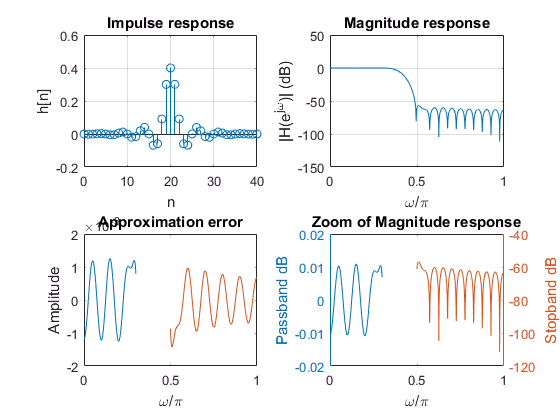


% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, H_dB);
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})| (dB)');
title('Magnitude response');

subplot(2,2,3)
p=(1:0.3*(npts-1)+1); % 1~2000
s=(0.5*(npts-1)+1:npts); % 2001~4000
err1=A(p)-1;
err2=A(s);
plot(om(p)/pi, err1);
hold on
plot(om(s)/pi, err2);
ylabel('Amplitude');
hold off
xlabel('\omega/\pi');
title('Approximation error')

subplot(2,2,4)
yyaxis left
plot(om(p)/pi,20*log10(abs(H(p))));
ylabel('Passband dB');
hold on
yyaxis right
plot(om(s)/pi,20*log10(abs(H(s))));
ylabel('Stopband dB');
hold off
xlabel('\omega/\pi');
title('Zoom of Magnitude response')

6. (12%) Design a highpass FIR filter to satisfy the specifications: $\omega_p = 0.5\pi$, $\omega_s = 0.3\pi$, and $A_s=50$dB.

 (a)  Use Kaiser window to obtain a minimum length linear-phase filter. Provide a plot similar to Figure 10.12.

clc;clear;close all;

% LPF design (same with 5.)
A=50;
wc=0.4*pi;
beta=0.5842*(A-21)^0.4+0.07886*(A-21);
M=ceil((A-8)/(2.285*0.2*pi))+1;
L=M+1;
alpha=M/2;
n=0:M;
hd=wc*sinc(wc*(n-alpha));
f=[0 0.3 0.5 1];
A=[0 0 1 1];
h=fir2(M+1,f,A,kaiser(L+1,beta));

% reverse the frequency response of LPF to get HPF
npts=1001;
[H,om]=freqz(h,1,npts);
A=amplresp(h,om);

*** Type-1 Linear-Phase Filter ***



% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, 20*log10(abs(H)));
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})| (dB)');
title('Magnitude response');

subplot(2,2,3)
p=(1:0.3*(npts-1)+1);
s=(0.5*(npts-1)+1:npts);
err1=A(p)-1;
err2=A(s);
plot(om(p)/pi, err1);
hold on
plot (om(s)/pi, err2);
ylabel('Amplitude');
hold off
xlabel('\omega/\pi');
title('Approximation error')

subplot(2,2,4)
yyaxis left
plot(om(p)/pi,20*log10(abs(H(p))));
ylabel('Passband dB');
hold on
yyaxis right
plot(om(s)/pi,20*log10(abs(H(s))));
ylabel('Stopband dB');
hold off
xlabel('\omega/\pi');
title('Zoom of Magnitude response')

 (b)  Repeat (a) using the fir1 function. 

h=fir1(L,0.4,'high',kaiser(L+1,beta));

% calculate
npts=1001;
[H,om]=freqz(h,1,npts);
A=amplresp(h,om);

*** Type-1 Linear-Phase Filter ***


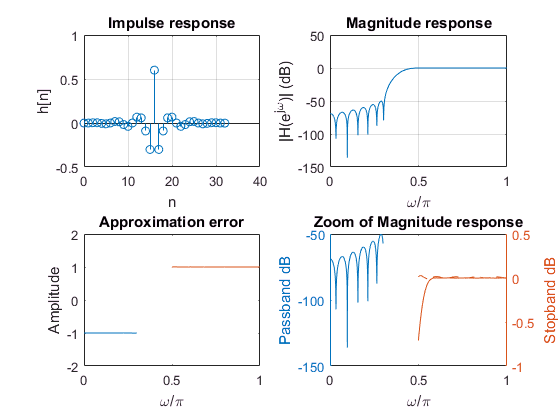


% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, 20*log10(abs(H)));
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})| (dB)');
title('Magnitude response');

subplot(2,2,3)
p=(1:0.3*(npts-1)+1);
s=(0.5*(npts-1)+1:npts);
err1=A(p)-1;
err2=A(s);
plot(om(p)/pi, err1);
hold on
plot (om(s)/pi, err2);
ylabel('Amplitude');
hold off
xlabel('\omega/\pi');
title('Approximation error')

subplot(2,2,4)
yyaxis left
plot(om(p)/pi,20*log10(abs(H(p))));
ylabel('Passband dB');
hold on
yyaxis right
plot(om(s)/pi,20*log10(abs(H(s))));
ylabel('Stopband dB');
hold off
xlabel('\omega/\pi');
title('Zoom of Magnitude response')

7. (12%) In this problem we reproduce Figures 10.4 and 10.5. For each of the following linearphase FIR filters described by $h[n]$, obtain impulse response, amplitude response, magnitude response, and pole-zero plots in one figure window. For frequency response plots use the interval $−2\pi ≤ ω ≤ 2π$.

 (a) Type-I filter: $h[n] =\{1, 2, 3, −2, 5, −2, 3, 2, 1\}$. 

clc;clear;close all;

h=[1 2 3 -2 5 -2 3 2 1];
om=linspace(-pi, pi, 360);
om2=linspace(-2*pi, 2*pi, 2*360);

% calculate
H=freqz(h,1,om2);
A=amplresp(h,om);

*** Type-1 Linear-Phase Filter ***


H_mag=abs(H);

% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, A);
grid on;
xlabel('\omega/\pi');
ylabel('A(e^{j\omega})');
title('Amplitude response');

subplot(2,2,3)
plot(om2/pi, H_mag);
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
title('Magnitude response');

subplot(2,2,4)
zplane(h,[1]);

(b) Type-II filter: $h[n] = \{1, 2, 3, −2, −2, 3, 2, 1\}$. 

h=[1 2 3 -2 -2 3 2 1];
om=linspace(-pi, pi, 360);
om2=linspace(-2*pi, 2*pi, 2*360);

% calculate
H=freqz(h,1,om2);
A=amplresp(h,om);

*** Type-2 Linear-Phase Filter ***


H_mag=abs(H);

% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, A);
grid on;
xlabel('\omega/\pi');
ylabel('A(e^{j\omega})');
title('Amplitude response');

subplot(2,2,3)
plot(om2/pi, H_mag);
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
title('Magnitude response');

subplot(2,2,4)
zplane(h,[1]);

(c) Type-III filter: $h[n] = \{1, 2, 3, −2, 0, 2, −3, −2, −1\}$. 

h=[1 2 3 -2 0 2 -3 -2 -1];
om=linspace(-pi, pi, 360);
om2=linspace(-2*pi, 2*pi, 2*360);

% calculate
H=freqz(h,1,om2);
A=amplresp(h,om);

*** Type-3 Linear-Phase Filter ***


H_mag=abs(H);

% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, A);
grid on;
xlabel('\omega/\pi');
ylabel('A(e^{j\omega})');
title('Amplitude response');

subplot(2,2,3)
plot(om2/pi, H_mag);
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
title('Magnitude response');

subplot(2,2,4)
zplane(h,[1]);

(d) Type-IV filter: $h[n] = \{1, 2, 3, −2, 2, −3, −2, −1 \}$.   

h=[1 2 3 -2 2 -3 -2 -1];
om=linspace(-pi, pi, 360);
om2=linspace(-2*pi, 2*pi, 2*360);

% calculate
H=freqz(h,1,om2);
A=amplresp(h,om);

*** Type-4 Linear-Phase Filter ***


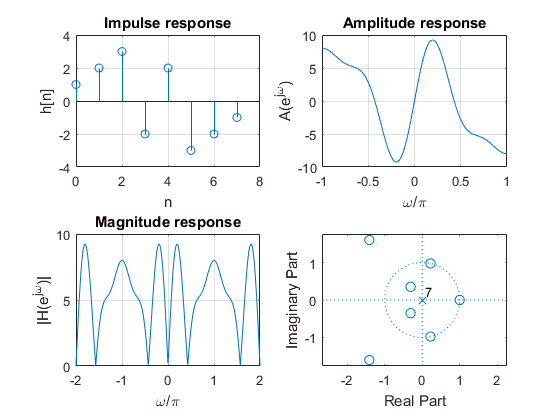

H_mag=abs(H);

% plot
subplot(2,2,1)
stem(0:length(h)-1,h);
grid on;
xlabel('n');
ylabel('h[n]');
title('Impulse response');

subplot(2,2,2)
plot(om/pi, A);
grid on;
xlabel('\omega/\pi');
ylabel('A(e^{j\omega})');
title('Amplitude response');

subplot(2,2,3)
plot(om2/pi, H_mag);
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
title('Magnitude response');

subplot(2,2,4)
zplane(h,[1]);

8. (18%) Consider a Blackman window of length $L = 21$. 

(a) Compute and plot the log-magnitude response in dB over $−π ≤ ω ≤ π$. In the plot measure and show the value of the peak of the first sidelobes. 

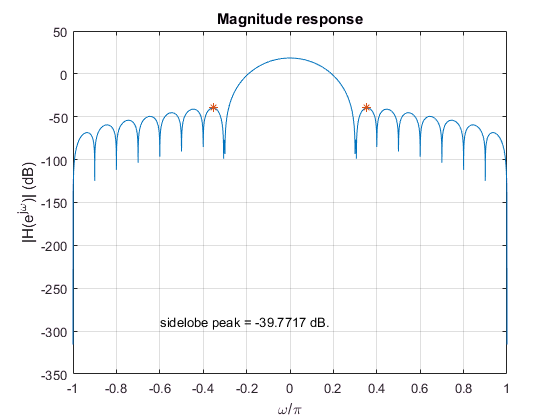

clc;clear;close all;

w=blackman(21)';
om=linspace(-pi, pi, 3600);
H=freqz(w,1,om);
H_dB=20*log10(abs(H));

figure(1)
plot(om/pi, H_dB);
hold on
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})| (dB)');
title('Magnitude response');
grid on;
[pks,locs]=findpeaks(H_dB,om,'SortStr','descend');
text(-0.6,-300,sprintf('sidelobe peak = %g dB.\n',pks(2)));
plot(locs(2:3)/pi,pks(2:3),'*');
hold off

(b) Compute and plot the accumulated amplitude response in dB using the cumsum function. In the plot measure and show the value of the peak of the first sidelobe.  

[A,om2]=amplresp(w);

*** Type-1 Linear-Phase Filter ***


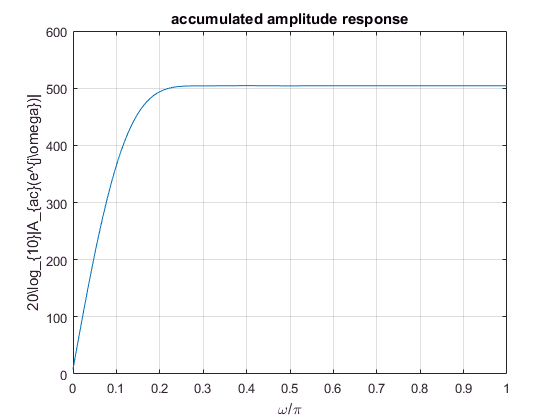

ac=cumsum(A);

figure(2)
plot(om2/pi, ac);
grid on;
xlabel('\omega/\pi');
ylabel('20\log_{10}|A_{ac}(e^{j\omega})|');
title('accumulated amplitude response');

(c) Repeat (a) and (b) for $L = 41$. 

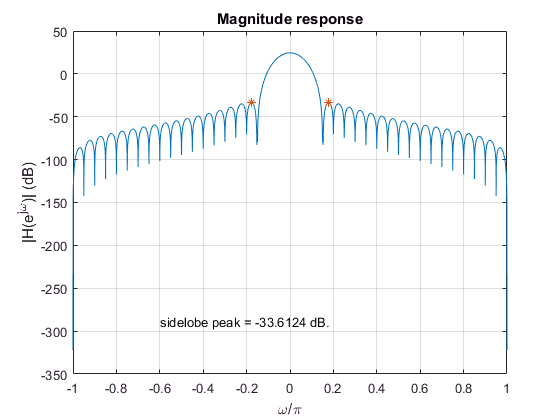

w=blackman(41)';
om=linspace(-pi, pi, 3600);
H=freqz(w,1,om);
H_dB=20*log10(abs(H));

figure(3)
plot(om/pi, H_dB);
hold on
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})| (dB)');
title('Magnitude response');
grid on;
[pks,locs]=findpeaks(H_dB,om,'SortStr','descend');
text(-0.6,-300,sprintf('sidelobe peak = %g dB.\n',pks(2)));
plot(locs(2:3)/pi,pks(2:3),'*');
hold off


[A,om2]=amplresp(w);

*** Type-1 Linear-Phase Filter ***


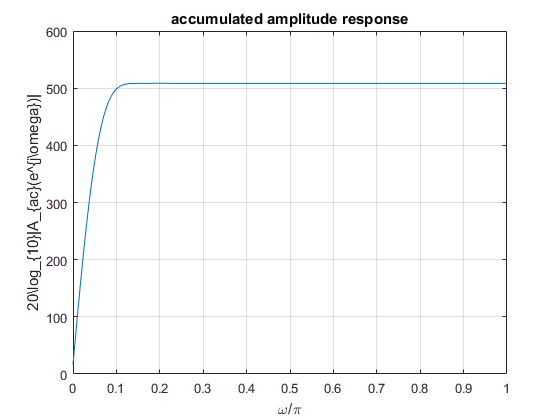

ac=cumsum(A);

figure(2)
plot(om2/pi, ac);
grid on;
xlabel('\omega/\pi');
ylabel('20\log_{10}|A_{ac}(e^{j\omega})|');
title('accumulated amplitude response');

9. (18%) An ideal lowpass filter has a cutoff frequency of $ω_c= 0.4π$. We want to obtain a length $L=40$ linear-phase FIR filter using the frequency-sampling method. 

(a) Let the sample at $\omega_c$ be equal to 0.5. Obtain the resulting impulse response $h[n]$. Plot the log-magnitude response in dB and determine the minimum stopband attenuation.

M=39;
L=40;

(b) Now vary the value of the sample at $\omega_c$ and find the largest minimum stopband attenuation. Obtain the resulting impulse response $h[n]$ and plot the log-magnitude response in dB in the plot window of (a). 

(c) Compare your results with those obtained using the fir2 function (choose hamming window). 

f=[0 0.4 1]

f =          0    0.4000    1.0000


A=[1 0.5 0]

A =     1.0000    0.5000         0


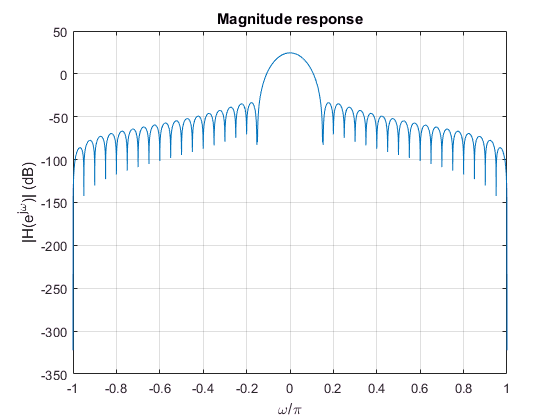


h=fir2(M,f,A);

om=linspace(-pi, pi, 3600);
H=freqz(w,1,om);
H_dB=20*log10(abs(H));

figure(9)
plot(om/pi, H_dB);
grid on;
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})| (dB)');
title('Magnitude response');


% Calculate the minimum stopband attenuation
[pks,locs]=findpeaks(abs(H),om,'SortStr','descend'); % find delta_s=pks(2)
As=-20*log10(pks(2));
fprintf("As = %f dB",As);

As = 33.612395 dB